# Fourier Analysis of the fracture aperture distribution

The objective of this exercise is to implement an idea discussed with Nicola on Friday Feb 25th regarding analyzing fracture specific stiffness. Fracture specific stiffness is defined as "the average applied stressd divided by the average displacement across the fracture interface in excess of the displacement that would occur if the fracture were not present." (Hopkins et al. 1987).

The first thing to do is learn more about Fast-Fourier Transforms (FFT). I will be referring to (Cerna and Harvey, 2000) for guidance in understanding how to use FFT in analysing my data. I want to note that generally speaking, FFT is applied to time-series data i.e. data that change over time. For analysing fractures, we are interested in spacially variable data not time variant, so that will be a distict difference in using FFT.

## Example in Matlab documentation

Define the domain of the calculation

Fs = 1000;            % Sampling frequency  [sample/time]             
T = 1/Fs;             % Sampling period     [time/sample[
L = 1500;             % Length of signal    [sample]
t = (0:L-1)*T;        % Time vector         [time]

Form a signal containing a 50 Hz sinusoid of amplitude 0.7 and a 120 Hz sinusoid of amplitude 1.

S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);

ِCorrupt the signal with zero-mean white noise with a variance of 4.

X = S + 2*randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal `X(t)`.

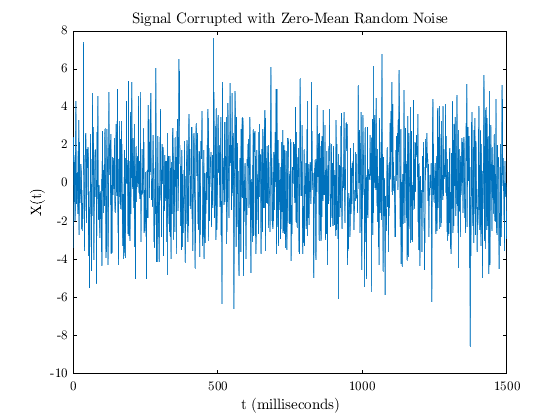

figure
plot(1000*t,X)
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

Compute the Fourier transform of the signal. 

Y = fft(X);

Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length `L`.

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1`. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.

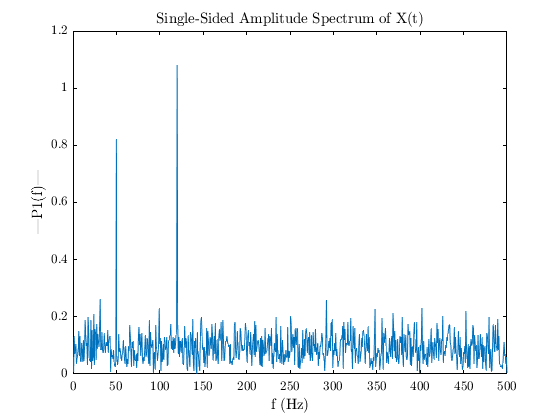

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Now, take the Fourier transform of the original, uncorrupted signal and retrieve the exact amplitudes, 0.7 and 1.0.

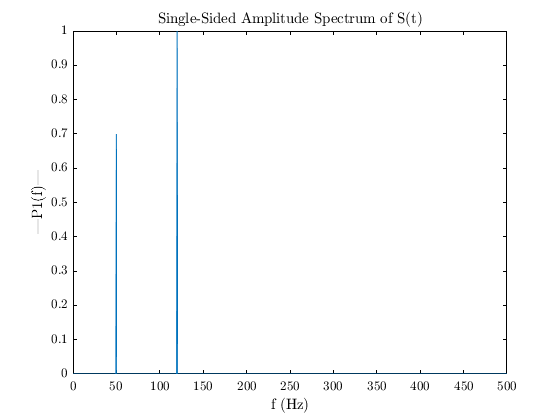

Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

*Copyright 2012 The MathWorks, Inc.*

## Desconstructing the Matlab example for better understanding

The following [link](https://medium.com/analytics-vidhya/breaking-down-confusions-over-fast-fourier-transform-fft-1561a029b1ab) is useful in guiding through applyig `fft` 

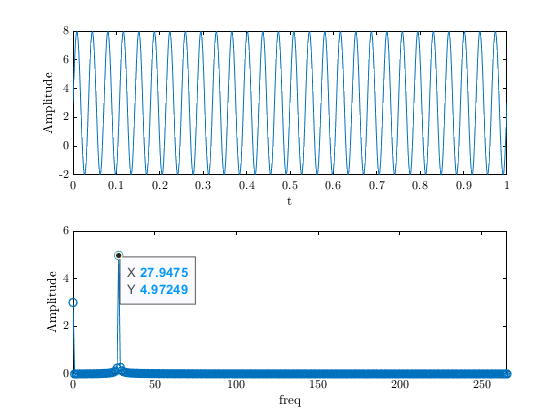

% consider a time series signal that is purely sinosoidal
freq = 28;
T = 1/freq;
nSamplesPerCycle = 20;
dt = T/(nSamplesPerCycle-1); % sampling interval [time/sample]
samplingFreq = 1/dt;         % sampling frequencye [sample/time]
nCyles = 10;
t = 0:dt:1;
nSamples = length(t);
y = @(t,f) 5*sin(2*pi*f*t)+3;

figure
subplot(2,1,1);
plot(t,y(t,freq),'-')
xlabel('t');
ylabel('Amplitude')
xlim([0 t(end)])

Y = fft(y(t,freq));
N = length(Y);

% in the following, normalizing by the number of samples is simply part of
% the algorith. I did not look much further into it, and I don't think it
% matters too much
P2 = abs(Y/N);

% computing the signle side band, or singles-sided spectrum, we take the
% first half of P2. Note that P2(1) is the DC or zero-frequencye componenet
P1 = P2(1:floor(N/2)+1);

% since the first element of the P1 is the DC element, we multiple the rest
% by 2 which is equivalent to applying the Hilbert transform (based on the
% link above!)
P1(2:end) = 2*P1(2:end);
 
% to find the xaxis, we need to do the following. I need to study this
% further to better understand it.
freqFFT = (0:floor(N/2))*(samplingFreq/((N)));

subplot(2,1,2);
signalLength = length(t);
faxis = samplingFreq*(0:signalLength-1)/signalLength-signalLength/2;
plot(freqFFT,P1,'-o')
xlim([freqFFT(1) freqFFT(end)]);
ylabel('Amplitude');
xlabel('freq');

## Generating an example siganl

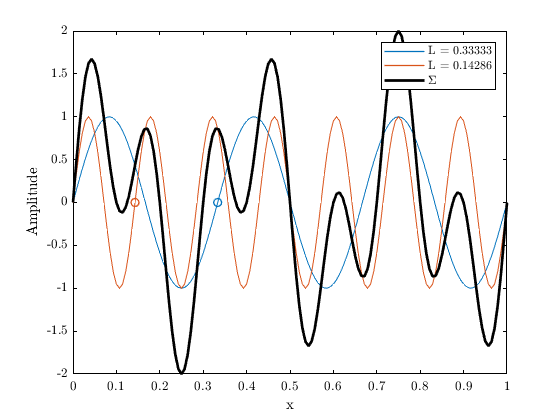

% defining the 1d spatial domain of interest

% I will come back to the following commented lines
%{
imageResolution     = 33.3e-3; % [mm/sample]
samplingFrequency   = 1/(imageResolution * 1000)
sampleNominalDiameter = 25; % [mm]
%}
k = [3 7];           % wave numbers
lambda = 1./k;             % wave lengths
dx = 0.05*min(lambda);      % [length/sample] ~ "sampling period"
dX = 1/dx;                  % [sample/length] ~ "sampling frequency"
x = 0:dx:3*max(lambda);

phaseShifts = zeros(size(lambda)); %linspace(0,pi/2,length(lambda)); % phase


% computing the resultant signal and plotting it
f = zeros(size(x));
figure

% plotting the wave length markers
for i = 1:length(lambda)
    l = plot(lambda(i), 0,'o'); hold on;
    l.Annotation.LegendInformation.IconDisplayStyle = 'off';
end

% extracting the color imformation to match the following line plots
ax = gca;
lineColors = {ax.Children.Color};
% reverse the order of lineColors
lineColors = {lineColors{end:-1:1}};

% plotting the signals
for i = 1:length(lambda)
    tmp = sin(2*pi*k(i)*x+phaseShifts(i));
   f = f + tmp;
   plot(x,tmp,'DisplayName',['L = ',num2str(lambda(i))],'Color',lineColors{i});
end

% plotting signal combination
plot(x,f,'LineWidth',2,'Color','k','DisplayName','$\Sigma$');
legend
xlabel('x');
ylabel('Amplitude');

Computing the `fft` of $f(x)$

Y = fft(f)

Y =    0.0000 + 0.0000i   0.0115 - 0.5146i   0.0661 - 1.4814i   4.7230 -70.5531i  -0.0826 + 0.9240i   0.0518 - 0.4629i   0.3192 - 2.3738i  10.7840 -68.5820i  -0.7758 + 4.3061i  -0.4790 + 2.3564i  -0.3837 + 1.6936i  -0.3371 + 1.3478i  -0.3097 + 1.1306i  -0.2918 + 0.9790i  -0.2792 + 0.8660i  -0.2701 + 0.7777i  -0.2631 + 0.7064i  -0.2576 + 0.6473i  -0.2532 + 0.5972i  -0.2497 + 0.5541i  -0.2467 + 0.5166i  -0.2443 + 0.4834i  -0.2422 + 0.4539i  -0.2404 + 0.4273i  -0.2389 + 0.4033i  -0.2376 + 0.3814i  -0.2364 + 0.3614i  -0.2354 + 0.3429i  -0.2345 + 0.3258i  -0.2337 + 0.3098i  -0.2329 + 0.2950i  -0.2323 + 0.2811i  -0.2317 + 0.2680i  -0.2312 + 0.2556i  -0.2307 + 0.2439i  -0.2303 + 0.2329i  -0.2299 + 0.2223i  -0.2295 + 0.2123i  -0.2292 + 0.2027i  -0.2289 + 0.1935i  -0.2286 + 0.1847i  -0.2284 + 0.1763i  -0.2282 + 0.1681i  -0.2279 + 0.1602i  -0.2277 + 0.1526i  -0.2276 + 0.1453i  -0.2274 + 0.1381i  -0.2272 + 0.1312i  -0.2271 + 0.1245i  -0.2270 + 0.1179i


L = length(f);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

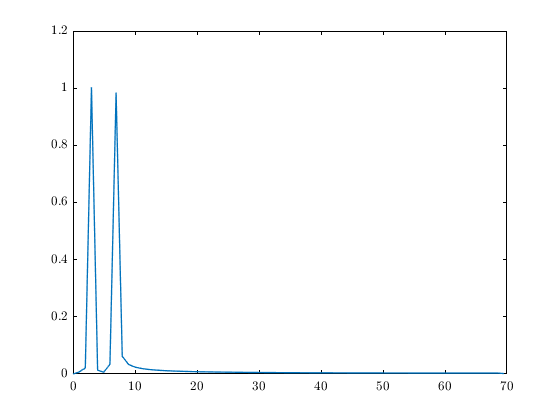

P1(2:end-1) = 2*P1(2:end-1);

K = dX*(0:(L/2))/L; % wavenumber (frequency)
figure
plot(K,P1)

# References

Cerna, M., and A. F. Harvey, 2000, The Fundamentals of FFT-Based Signal Analysis and Measurement: Application Note 041, National Instruments.  

Hopkins, D. L., N. G. W. Cook, and L. R. Myer, 1987, Fracture Stiffness And Aperture As A Function Of Applied Stress And Contact Geometry: , ARMA-87-0673.

Chuan-Zheng Lee (2017). *Signals and the frequency domain*. (pdf). Available from: <https://web.stanford.edu/class/archive/engr/engr40m.1178/slides/signals.pdf>. [Accessed 02/28/2022 ].